
%firc 
Td = 0.8;%dac delay,0.8个时钟周期，Ts对时钟周期进行归一化

%1/s,1/s^2,1/s^3的脉冲响应
x1 = impulse(c2d(tf([1],[1 0]),1),10)

x1 =      0
     1
     1
     1
     1
     1
     1
     1
     1
     1


x2 = impulse(c2d(tf([1],[1 0 0]),1),10)

x2 =          0
    0.5000
    1.5000
    2.5000
    3.5000
    4.5000
    5.5000
    6.5000
    7.5000
    8.5000


x3 = impulse(c2d(tf([1],[1 0 0 0]),1),10)

x3 =          0
    0.1667
    1.1667
    3.1667
    6.1667
   10.1667
   15.1667
   21.1667
   28.1667
   36.1667



%理想的 Hs=k1/s+k2+s^2+k3/s^3;
imp_lct = x1*k1+x2*k2+x3*k3;

Fz = tf([1,1,1,1,1,1],[6,0,0,0,0,0],1)%fir滤波器的传输函数

Fz =
 
  z^5 + z^4 + z^3 + z^2 + z + 1
  -----------------------------
              6 z^5
 
Sample time: 1 seconds
Discrete-time transfer function.



%先不考虑dac delay,只考虑fir延迟问题
x1d = impulse((c2d(tf([1],[1 0]),1)*Fz),10)

x1d =          0
    0.1667
    0.3333
    0.5000
    0.6667
    0.8333
    1.0000
    1.0000
    1.0000
    1.0000


x2d = impulse((c2d(tf([1],[1 0 0] ),1)*Fz),10)

x2d =          0
    0.0833
    0.3333
    0.7500
    1.3333
    2.0833
    3.0000
    4.0000
    5.0000
    6.0000


x3d = impulse((c2d(tf([1],[1 0 0 0]),1)*Fz),10)

x3d =          0
    0.0278
    0.2222
    0.7500
    1.7778
    3.4722
    6.0000
    9.5000
   14.0000
   19.5000



M= 6;
k3d = k3;
k2d = k2+k3*(M-1)/2;
k1d = k1+k2*(M-1)/2+k3*(M-1)*(M-2)/12;

imp_lct_delay = x1d*k1d+x2d*k2d+x3d*k3d;

delta = imp_lct - imp_lct_delay

delta =          0
    0.5433
    0.5087
    0.4444
    0.3431
    0.1974
    0.0000
    0.0000
    0.0000
    0.0000


%(k3d*x3+K2d*x2+k1d*x1)*Fz + Fcz = k3*x3+k2*x2+k1*x1

kc = delta(1:6,1)

kc =          0
    0.5433
    0.5087
    0.4444
    0.3431
    0.1974


kc = kc'

kc =          0    0.5433    0.5087    0.4444    0.3431    0.1974



Fcz = tf(kc,[1,0,0,0,0,0],1)

Fcz =
 
  0.5433 z^4 + 0.5087 z^3 + 0.4444 z^2 + 0.3431 z + 0.1974
  --------------------------------------------------------
                            z^5
 
Sample time: 1 seconds
Discrete-time transfer function.




xc = impulse(Fcz,10)

xc =          0
    0.5433
    0.5087
    0.4444
    0.3431
    0.1974
         0
         0
         0
         0


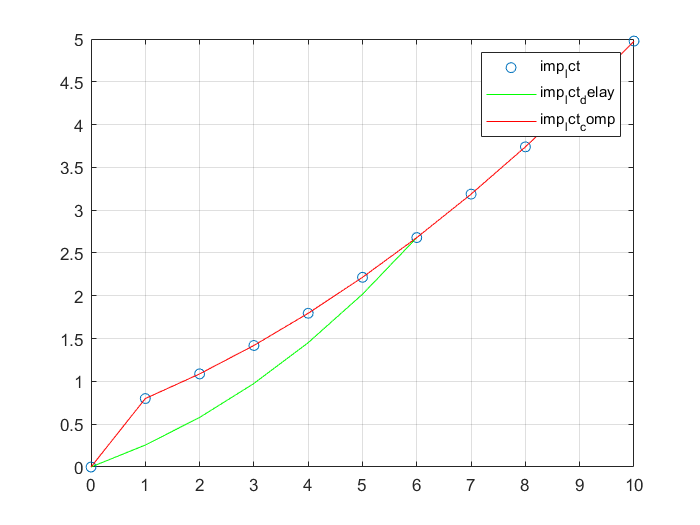

imp_lct_comp = x1d*k1d+x2d*k2d+x3d*k3d + xc;



plot_imp_reponse_delay = 1;

if plot_imp_reponse_delay == 1
figure;
plot(0:10,imp_lct,'o');
hold on;
plot(0:10,imp_lct_delay,'g');

hold on;

plot(0:10,imp_lct_comp,'r');
legend('imp_lct','imp_lct_delay','imp_lct_comp');
grid on;

end


%调整k1，k2,k3的值
k1=k1d

k1 = 1.3540

k2=k2d

k2 = 0.3541

k3=k3d

k3 = 0.0440